# 基于单系数除法模型对普通广角/鱼眼镜头图像去畸变实现

崔星星 2023.5.11

Email: cuixingxing150@gmail.com

本示例展示了通过设计单个畸变系数[1]对人工设计的畸变图像进行了去畸变过程。其中使用了ransac/拟合圆的方式，距离函数设计为最小区域法的"直线度"误差，在在线去畸变任务中有实际应用意义！

## 图像数据

复现参考论文[1]理论，为方便起见，设计了一棋盘网格图像进行去畸变研究，共10*14个黑白网格，每个网格宽度为50 pixel，在MATLAB种非常方便的进行了如下代码的可视化显示。

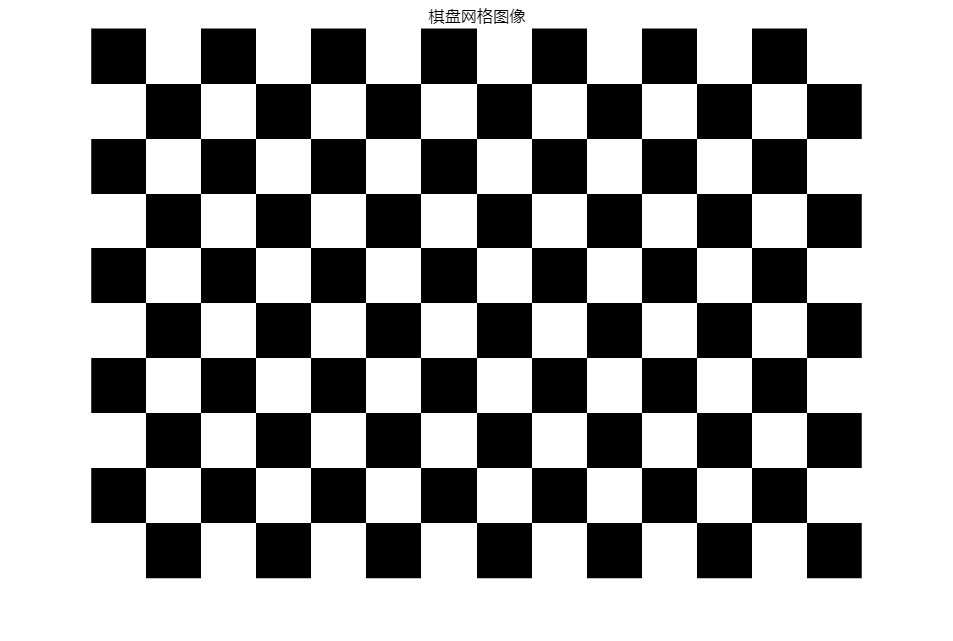

representImage = checkerboard(50,5,7);
representImage = representImage>0.5;
imshow(representImage);
title("棋盘网格图像")

设计该图像的单个畸变系数为-2*10^(-6)，负数为桶形畸变。

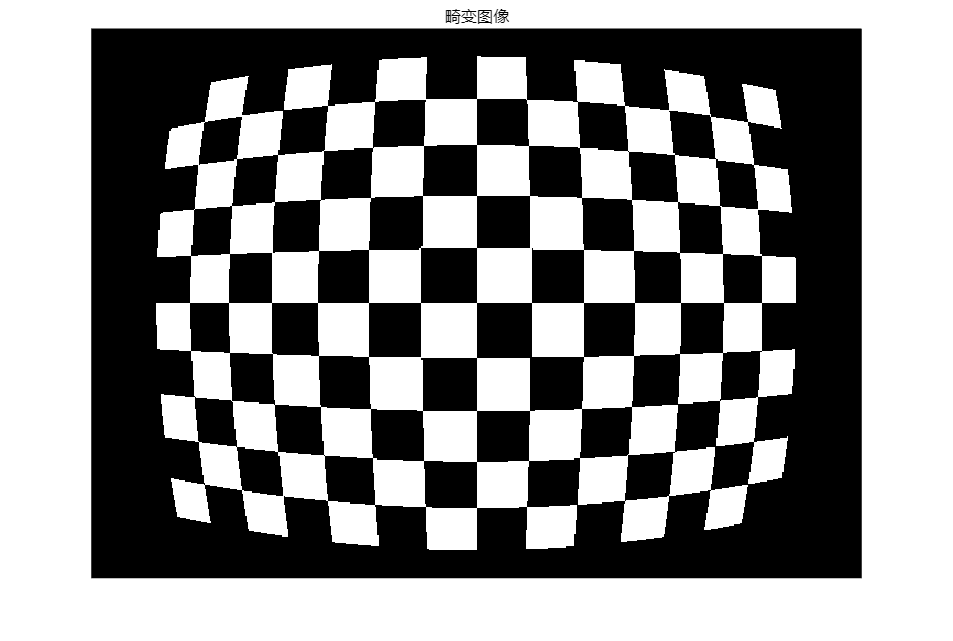

lambda = -2*10^(-6);
[H,W,~] = size(representImage);
[x_d,y_d] = meshgrid(1:W,1:H);
x_c = W/2;
y_c = H/2;
r = sqrt((x_d-x_c).^2+(y_d-y_c).^2);
x_u = x_c+(x_d-x_c)./(1+lambda*r.^2);
y_u = y_c+(y_d-y_c)./(1+lambda*r.^2);
distortedImage = images.internal.interp2d(representImage,x_u,y_u,...
    "linear",0, false);
imshow(distortedImage)
title("畸变图像")

## Ransac/最小二乘拟合圆

本节主要使用最小二乘法拟合圆，再根据除法模型相关公式计算得到中间变量表格M。

warning off;
[imagePoints,boardSize] = detectCheckerboardPoints(distortedImage);
imshow(distortedImage);hold on;
plot(imagePoints(:,1),imagePoints(:,2),'ro-',LineWidth=2)
colNumArcs = boardSize(2)-1;
rowNumArcs = boardSize(1)-1;

fitFcn = @(points)robustLeastSquareCircle(points);% test_leastSquareFitCircle.m
distFcn = @(model, points)((points(:,1)-model(1)).^2+(points(:,2)-model(2)).^2-model(3).^2).^2;
sampleSize = 3;
maxDistance = 5000;

M = table([],{},[],VariableNames=["arcs","points","resnorm"]); % arcs: [A,B,C],points:[x,y]

列弧线拟合和计算：

for i = 1:colNumArcs
    currArcInds = (i-1)*rowNumArcs+1: i*rowNumArcs;
    currPts = imagePoints(currArcInds,:);
    % [modelRansac,inlierIdx] = ransac(currPts,fitFcn,distFcn,sampleSize,maxDistance);
    % if sum(inlierIdx)>=3
    [modelRobust,res] = robustLeastSquareCircle(currPts);
    J = plot(currPts(:,1),currPts(:,2),'bo');
    h = viscircles(modelRobust(1:2),modelRobust(3),Color="blue");
    % delete(h);delete(J)
    A = -2*modelRobust(1);% 2009_(经典_重点_大连理工)A Simple Method of Radial Distortion Correction with Centre of Distortion Estimation
    B = -2*modelRobust(2);
    C = (modelRobust(1))^2+(modelRobust(2))^2-(modelRobust(3))^2;
    M(end+1,:) = table([A,B,C],{currPts},res);
    % end
end


可能存在局部最小值。

lsqnonlin 已停止，因为平方和相对于其初始值的最终变化小于函数容差值。

<停止条件详细信息>

可能存在局部最小值。
lsqnonlin 已停止，因为当前步长的相对大小小于
步长容差的值。

<停止条件详细信息>

可能存在局部最小值。
lsqnonlin 已停止，因为

行弧线拟合和计算：

for i = 1:rowNumArcs
    currArcInds = i:rowNumArcs:rowNumArcs*colNumArcs;
    currPts = imagePoints(currArcInds,:);
    % [modelRansac,inlierIdx] = ransac(currPts,fitFcn,distFcn,sampleSize,maxDistance);
    % if sum(inlierIdx)>=3
    [modelRobust,res] = robustLeastSquareCircle(currPts);
    J = plot(currPts(:,1),currPts(:,2),'bo');
    h = viscircles(modelRobust(1:2),modelRobust(3),Color="blue");
    % delete(h);delete(J)
    A = -2*modelRobust(1);% 2009_(经典_重点_大连理工)A Simple Method of Radial Distortion Correction with Centre of Distortion Estimation
    B = -2*modelRobust(2);
    C = (modelRobust(1))^2+(modelRobust(2))^2-(modelRobust(3))^2;
    M(end+1,:) = table([A,B,C],{currPts},res);
    % end
end


找到局部最小值。

优化已完成，因为梯度大小小于
函数容差的 1e-4 倍。

<停止条件详细信息>

找到局部最小值。

优化已完成，因为梯度大小小于
函数容差的 1e-4 倍。

<停止条件详细信息>

可能存在局部最小值。

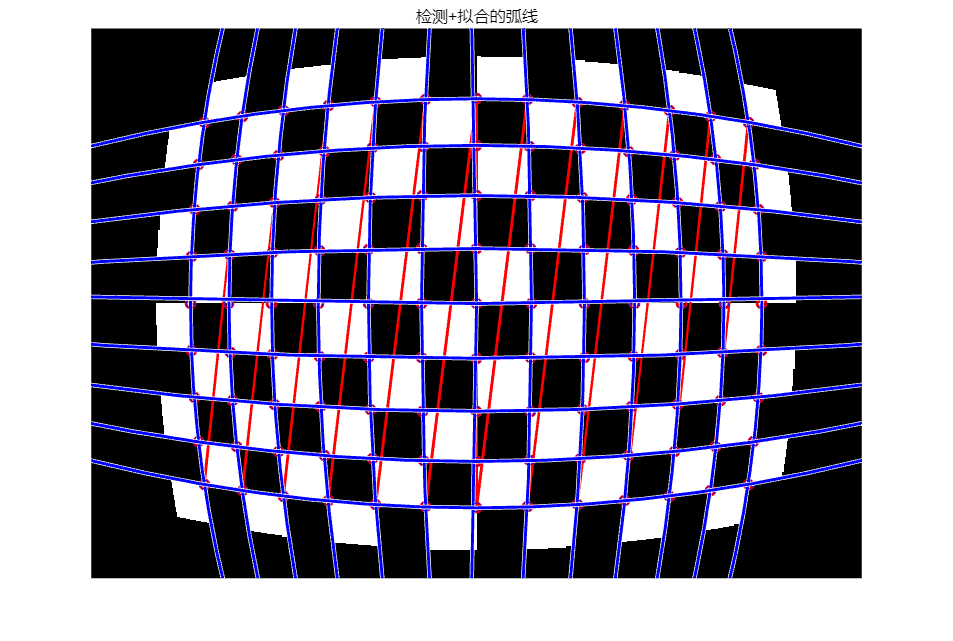

title("检测+拟合的弧线")

预览前几行中间表格变量M的数据：

head(M)

                      arcs                         points        resnorm  
    ________________________________________    ____________    __________
       -2360.2        -500.25     2.6826e+05    {9×2 double}         21878
       -2683.4        -499.73     3.8378e+05    {9×2 double}         13763
       -3230.4        -500.38     5.6648e+05    {9×2 double}         36537
       -4053.9        -499.85     8.5767e+05    {9×2 double}    1.3477e+05
       -5602.1        -499.46     1.4122e+06    {9×2 double}     9.136e+05
        -10190        -499.38     3.0346e+06    {9×2 double}    1.1411e+06
    1.6679e+05        -500.96    -5.8533e+07    {9×2 double}    1.4976e+08
        8352.3        -499.46    -3.4429e+06    {9×2 double}    2.1077e+06


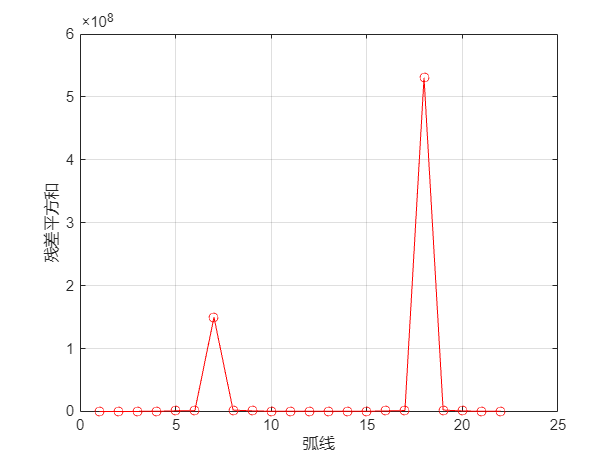

figure;
plot(M.resnorm,'ro-');grid on;
xlabel("弧线");
ylabel("残差平方和");

可以看出第7，18条弧线存在较大偏差，这主要是因为这两条弧线位于图像正中央，接近一条直线，拟合系数稳定性较差导致。

## 矫正图像

使用上面计算的表格中间变量M矩阵计算去畸变图，为了得到较好的效果，过滤了偏差较大的值。加之，为了批量进行处理，可以直接利用robustRectifyImage返回的mapX,mapY进行映射去畸变。

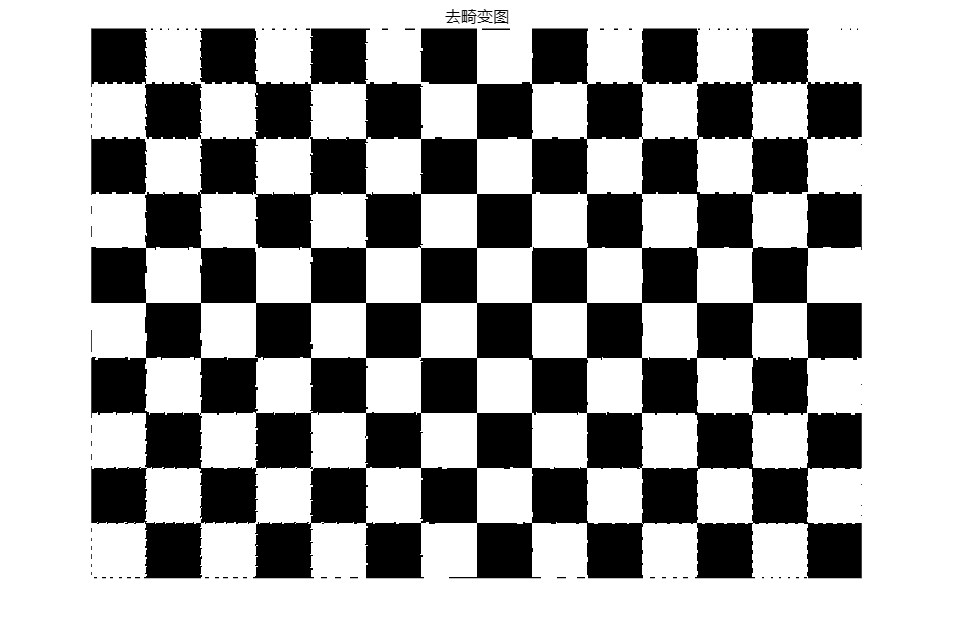

[undistortImage,mapX,mapY] = robustRectifyImage(distortedImage,M(M.resnorm<10^8,:));
imshow(undistortImage);
title("去畸变图")

## References

[1] Aiqi Wang,Tianshuang Qiu,L.-T. Shao, "A Simple Method of Radial Distortion Correction with Centre of Distortion Estimation",November 2009 Journal of Mathematical Imaging and Vision 35(3):165-172-35(3):165-172